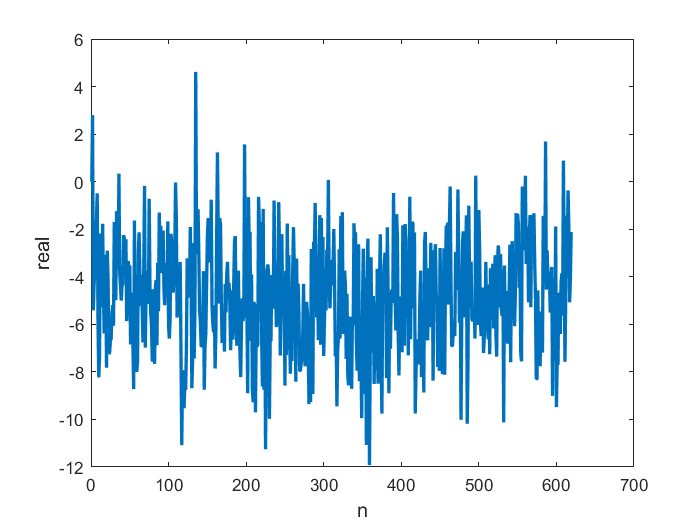

fname = input('enter filename ','s');
fid = fopen(fname,'rt');
floatcount = 0;
dummy = fscanf(fid,'%c',1);
if (dummy ~= ':')
    disp('error: initial colon not found');
else
%process data from this file
finished = 0;
while (finished == 0)
    % move to next line
    while (fscanf(fid,'%c',1) ~= ':'); end
    % get number of 32-bit hex values on line
    N = hex2dec(fscanf(fid,'%c',2))/4;
    % read and discard next 6 characters
    fscanf(fid,'%c',6);
    if (N > 0)
        for i=1:N
          % read 8 character hex string and convert to IEEE float 754 single
          hexstring = fscanf(fid,'%c',8);
          reordered(1) = hexstring(7);
          reordered(2) = hexstring(8);
          reordered(3) = hexstring(5);
          reordered(4) = hexstring(6);
          reordered(5) = hexstring(3);
          reordered(6) = hexstring(4);
          reordered(7) = hexstring(1);
          reordered(8) = hexstring(2);
            memdata(floatcount+1)= hexsingle2num(reordered);
          floatcount = floatcount+1;
        end
    else
    finished = 1;
    end
end
end
fclose(fid);          

N = floatcount;
figure;
set(gcf,'numberTitle','off')
set(gcf,'name','real data read from the microcontroller memory in Keil uVision 5')
plot(0:(floatcount-1),memdata(1:1:floatcount),'LineWidth',2.0);
%bar(0:(floatcount-1),memdata(1:1:floatcount)/2,0.2);grid on
xlabel('n','FontSize',12,'FontName','times');
ylabel('real','FontSize',12,'FontName','times');

% c1 = [];
% c2 = [];
% c3 = [];
% c4 = [];
% c5 = [];
% 
% for i=1:3150
%     if(mod(i,5) == 0)
%         c1 = [c1, memdata(i)];
%     elseif(mod(i,5) == 1)
%         c2 = [c2, memdata(i)];
%     elseif(mod(i,5) == 2)
%         c3 = [c3, memdata(i)];
%     elseif(mod(i,5) == 3)
%         c4 = [c4, memdata(i)];
%     elseif(mod(i,5) == 4)
%         c5 = [c5, memdata(i)];
%         
%     end 
% end